# Extracting Sensor Data from Cell Arrays

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

data = readtable("./data/sensorData.csv");
headY_redundant = readmatrix("./data/headY_redundant.txt");
headX = rmmissing(data.headX);
headY = rmmissing(data.headY);
headZ = rmmissing(data.headZ);
sensorData = {'Force on head in X direction', 'Force on head in Y direction', 'Force on head in Z direction'; headX, headY, headZ};
sensorData

sensorData = 2×3 cell array
    {'Force on head in X direction'}    {'Force on head in Y direction'}    {'Force on head in Z direction'}
    {3095×1 double                 }    {1205×1 double                 }    {3271×1 double                 }


## Task 1

The cell array `sensorData` contains data on the force on the head during a crash test. The first row contains descriptions of each numeric variable. The second row contains the measurements from each of three sensors.

numericData = sensorData(2, :)

numericData = 1×3 cell array
    {3095×1 double}    {1205×1 double}    {3271×1 double}


## Task 2

The cell array `numericData` contains three numeric column vectors. The `plot` function takes numeric input, so you will need to extract the contents of `numericData` and pass it to the plot function.

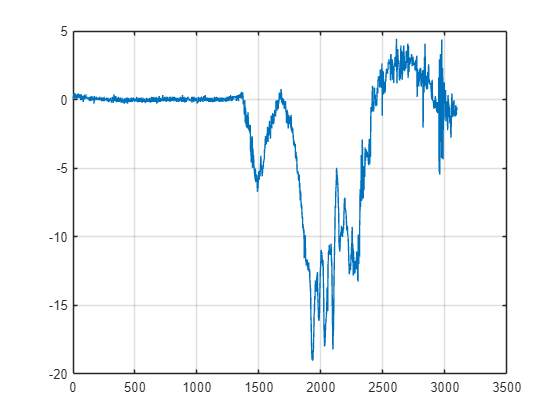

plot(numericData{1})
grid on

## Task 3

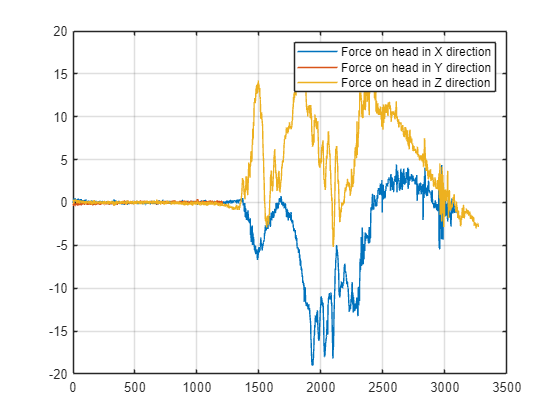

hold on
plot(numericData{2})
plot(numericData{3})
hold off
legend(sensorData(1, :))

## Task 4

In the plot you may have noticed that the second sensor's data is incomplete. That might be because the sensor stopped recording data on impact.

sensorData{2, 2} = 'Broken Sensor'

sensorData = 2×3 cell array
    {'Force on head in X direction'}    {'Force on head in Y direction'}    {'Force on head in Z direction'}
    {3095×1 double                 }    {'Broken Sensor'               }    {3271×1 double                 }


## Task 5

You can also remove bad data. To remove an element from an array, use parentheses and set the result to an empty array, `[]`.

numericData(2) = []

numericData = 1×2 cell array
    {3095×1 double}    {3271×1 double}


## Task 6

sensorData(:, 2) = []

sensorData = 2×2 cell array
    {'Force on head in X direction'}    {'Force on head in Z direction'}
    {3095×1 double                 }    {3271×1 double                 }


## Task 7

The variable `headY_redundant` contains data from a redundant sensor. To look at the properties of this variable, type

`whos` `headY_redundant`

You can simultaneously add data to a cell array and extend its size by updating the contents of a non-existent element.

numericData{end+1} = headY_redundant

numericData = 1×3 cell array
    {3095×1 double}    {3271×1 double}    {2241×1 double}
